## **Base Station Site**

Create a transmitter site on South Uncanoonuc Mountain in Goffstown, New Hampshire, US. The mountain is home to several transmitting facilities that serve the area. Define the transmitter site to represent a base station transmitting at 28 GHz with 1 Watt of power.

fq = 28e9; % 28 GHz
antHeight = 25; % m
txPowerDBm = 64; % Total transmit power in dBm
txPower = 10.^((txPowerDBm-30)/10); % Convert dBm to W
isd = 500;

## **Load JSON file**

NetworkNodes = jsondecode(fileread("Network\Backhauling-Network.json"));
UnassignedNodes = jsondecode(fileread("Network\Backhauling-Unassigned.json"));

## **Create Cellsites**

Each cell site has three transmitters corresponding to each cell. Create arrays to define the names, latitudes, longitudes, and antenna angles of each cell transmitter.

network = fieldnames(NetworkNodes);
unassigned = fieldnames(UnassignedNodes);
rxs = {};
txs = {};

for s = 1:length(network)
    tx = txsite("Name", NetworkNodes.(network{s}).Name, ...
    "Latitude", NetworkNodes.(network{s}).Position(2), ...
    "Longitude", NetworkNodes.(network{s}).Position(1), ...
    "AntennaHeight",antHeight,...
    "TransmitterPower",1, ...
    "TransmitterFrequency",fq);
    txs = [txs, tx];
    
    members = fieldnames(NetworkNodes.(network{s}).MEMBERS);
    for k = 1:length(members)
        rx = rxsite("Name", NetworkNodes.(network{s}).MEMBERS.(members{k}).Name, ...
        "Latitude", NetworkNodes.(network{s}).MEMBERS.(members{k}).Position(2), ...
        "Longitude", NetworkNodes.(network{s}).MEMBERS.(members{k}).Position(1), ...
        "AntennaHeight",antHeight);
        rxs = [rxs, rx]
    end
end

rxs =   rxsite with properties:

                   Name: 'Mastergucci National Youth Builder Program'
               Latitude: -26.3748
              Longitude: 28.4137
                Antenna: [1×1 dipole]
           AntennaAngle: 0
          AntennaHeight: 25
             SystemLoss: 0
    ReceiverSensitivity: -100


rxs =   1×2 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×3 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×4 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×5 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×6 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×7 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×8 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×9 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×10 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×11 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×12 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×13 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×14 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×15 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×16 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×17 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×18 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×19 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity



for s = 1:length(unassigned)
    rx = rxsite("Name", UnassignedNodes.(unassigned{s}).Name, ...
    "Latitude", UnassignedNodes.(unassigned{s}).Position(2), ...
    "Longitude", UnassignedNodes.(unassigned{s}).Position(1), ...
    "AntennaHeight",antHeight);
    rxs = [rxs, rx];
end
    
% Launch Site Viewer
viewer = siteviewer;

% Show sites on a map
show(txs);
show(rxs);
viewer.Basemap = 'openstreetmap';

## Create Antenna Element

Section 8.5 of ITU-R report [1] defines antenna characteristics for base station antennas. The antenna is modeled as having one or more antenna panels, where each panel has one or more antenna elements. Use Phased Array System Toolbox to implement the antenna element pattern defined in the report.

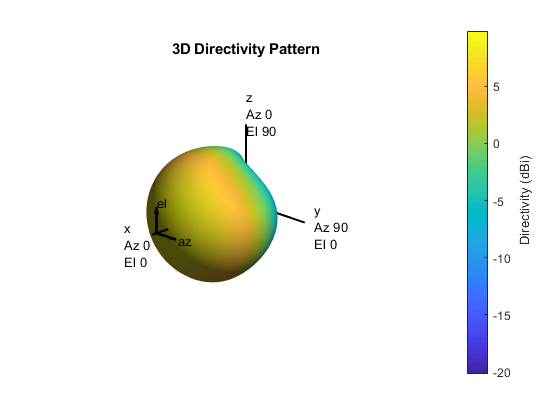

% Define pattern parameters
azvec = -180:180;
elvec = -90:90;
Am = 30; % Maximum attenuation (dB)
tilt = 0; % Tilt angle
az3dB = 65; % 3 dB bandwidth in azimuth
el3dB = 65; % 3 dB bandwidth in elevation

% Define antenna pattern
[az,el] = meshgrid(azvec,elvec);
azMagPattern = -12*(az/az3dB).^2;
elMagPattern = -12*((el-tilt)/el3dB).^2;
combinedMagPattern = azMagPattern + elMagPattern;
combinedMagPattern(combinedMagPattern<-Am) = -Am; % Saturate at max attenuation
phasepattern = zeros(size(combinedMagPattern));

% Create antenna element
antennaElement = phased.CustomAntennaElement(...
    'AzimuthAngles',azvec, ...
    'ElevationAngles',elvec, ...
    'MagnitudePattern',combinedMagPattern, ...
    'PhasePattern',phasepattern);
   
% Display radiation pattern
f = figure;
pattern(antennaElement,fq);

## Display SINR Map for Single Antenna Element

Visualize SINR for the test scenario using a single antenna element and the free space propagation model. For each colored location on the map, the signal source is the cell with the greatest signal strength, and all other cells are sources of interference.

% Assign the antenna element for each cell transmitter
for tx = txs
    tx.Antenna = antennaElement;
end

% Define receiver parameters using Table 8-2 (b) of Report ITU-R M.[IMT-2020.EVAL] 
bw = 20e6; % 20 MHz bandwidth
rxNoiseFigure = 7; % dB
rxNoisePower = -174 + 10*log10(bw) + rxNoiseFigure;
rxGain = 0; % dBi
rxAntennaHeight = 1.5; % m

## Create 8-by-8 Rectangular Antenna Array

Define an antenna array to increase directional gain and increase peak SINR values. Use Phased Array System Toolbox to create an 8-by-8 uniform rectangular array.

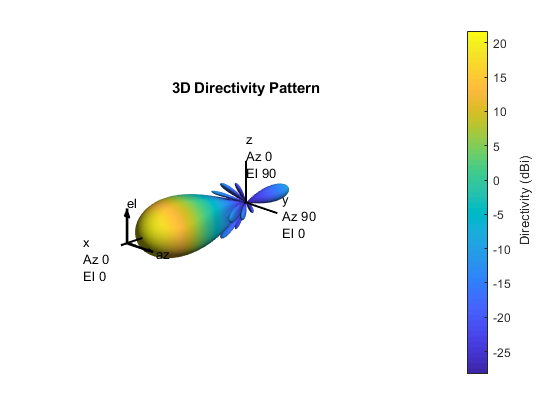

% Define array size
nrow = 8;
ncol = 8;

% Define element spacing
lambda = physconst('lightspeed')/fq;
drow = lambda/2;
dcol = lambda/2;

% Define taper to reduce sidelobes 
dBdown = 30;
taperz = chebwin(nrow,dBdown);
tapery = chebwin(ncol,dBdown);
tap = taperz*tapery.'; % Multiply vector tapers to get 8-by-8 taper values

% Create 8-by-8 antenna array
cellAntenna = phased.URA('Size',[nrow ncol], ...
    'Element',antennaElement, ...
    'ElementSpacing',[drow dcol], ...
    'Taper',tap, ...
    'ArrayNormal','x');
    
% Display radiation pattern
f = figure;
pattern(cellAntenna,fq);

## Create 3-by-3 Receiver Site Antenna Array

Create a 3-by-3 rectangular array from a reflector-backed vertical dipole antenna element. At each receiver site, point the array toward the base station and plot the radiation pattern on the map.

rxElement = reflectorDipoleElement(fq);

% Define array size
nrxrow = 3;
nrxcol = 3;
    
% Define element spacing
lambda = physconst("lightspeed")/fq;
drow = lambda/2;
dcol = lambda/2;

% Create antenna array
rxarray = phased.URA("Size",[nrxrow nrxcol], ...
    "Element",rxElement, ...
    "ElementSpacing",[drow dcol]);

% Assign array to each receiver site and point toward base station
for rx = rxs
    rx.Antenna = rxarray;
    
    tx = findTX(rx, txs, network, NetworkNodes);
    rx.AntennaAngle = angle(rx, tx);    
end

## Use Rectangular Patch Antenna as Array Element

The analysis above used an antenna element that was defined using the equations specified in the ITU-R report [1]. The antenna element needs to provide a maximum gain of 9.5 dBi and a front-to-back ratio of approximately 30 dB. Now replace the equation-based antenna element definition with a real antenna model using a standard half-wavelength rectangular microstrip patch antenna. The antenna element provides a gain of about 9 dBi, although with a lower front-to-back ratio. 

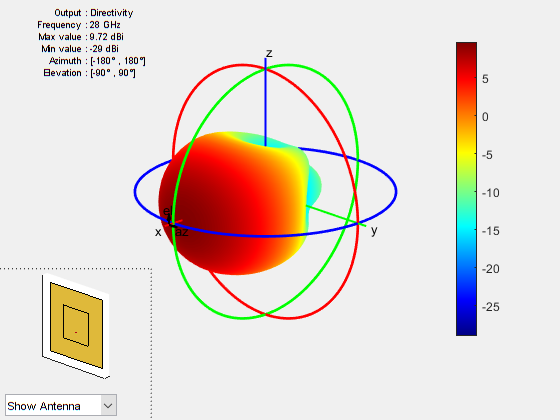

% Design half-wavelength rectangular microstrip patch antenna
patchElement = design(patchMicrostrip,fq);
patchElement.Width = patchElement.Length;
patchElement.Tilt = 90;
patchElement.TiltAxis = [0 1 0];

% Display radiation pattern
f = figure;
pattern(patchElement,fq)

## Display SINR Map using the Patch Antenna Element in the 8-by-8 Array

Update the SINR map for the Close-In propagation model [3] using the patch antenna as the array element. This analysis should capture the effect of deviations from an equation-based antenna specification as per the ITU-R report [1], including:

- Variations in peak gain

- Variations in pattern symmetry with spatial angles

- Variations in front-to-back ratios

% Assign the patch antenna as the array element
cellAntenna.Element = patchElement;

% Display SINR map
if isvalid(f)
    close(f)
end
sinr(txs,'close-in',...
    'ReceiverGain',rxGain, ...
    'ReceiverAntennaHeight',rxAntennaHeight, ...
    'ReceiverNoisePower',rxNoisePower, ...    
    'MaxRange',isd, ...
    'Resolution',isd/20)

## Add Path Loss Impairments

Additional attenuation of the signal occurs due to foliage and weather. Use Weissberger's model [3] to estimate path loss due to foliage, and use the rain propagation model to estimate signal strength in heavy rainfall. In the presence of path loss impairments, the estimated signal strength becomes weak and drops below the receiver sensitivity of -84 dBm.

% Assume that propagation path travels through 25 m of foliage
foliageDepth = 25;
L = 1.33*((fq/1e9)^0.284)*foliageDepth^0.588; % Weissberger model for d > 14
disp("Path loss due to foliage: " + L + " dB")

Path loss due to foliage: 22.7422 dB


% Assign foliage loss as static SystemLoss on each receiver site
for rx = rxs
    rx.SystemLoss = L;
end

% Compute signal strength with foliage loss
for rx = rxs
    rx.SystemLoss = L;
    
    tx = findTX(rx, txs, network, NetworkNodes);
    ss = sigstrength(rx,tx,"freespace");
    disp("Signal strength at " + rx.Name + ":")
    disp(ss + " dBm")
end

Signal strength at Mastergucci National Youth Builder Program:


-94.4302 dBm


Signal strength at duduza prototype early childhood development centre:


-95.1543 dBm


Signal strength at Iphahamiseng Primary School:


-95.1065 dBm


Signal strength at Esibonelwesihle High School:


-112.2482 dBm


Signal strength at Emzimkhulu Primary School:


-100.3563 dBm


Signal strength at Mom Sebone Secondary School:


-118.6131 dBm


Signal strength at Esibonelwesihle High School:


-112.2482 dBm


Signal strength at Duduza Primary School:


-106.53 dBm


Signal strength at SAsol garage:


31.9819 dBm


Signal strength at Edalinceba Primary School:


-114.1419 dBm


Signal strength at M.O.M. Seboni:


-120.8417 dBm


Signal strength at Roseview Primary School:


-115.6954 dBm


Signal strength at Sibonisiwe Primary School:


-124.7314 dBm


Signal strength at Thakgalang Primary School:


-115.6299 dBm


Signal strength at Zakheni Primary School:


-120.3449 dBm


Signal strength at Dan Radebe Primary School:


-115.7231 dBm


Signal strength at Mbusomusha Nursery & Pre - School:


-116.3368 dBm


Signal strength at duduza prototype early childhood development centre:


-95.1543 dBm


Signal strength at Asser Maloka Secondary School:


-127.0591 dBm



% Compute signal strength with foliage loss and heavy rain, which is between
% 4 mm and 16 mm per hour. Reference: http://wiki.sandaysoft.com/a/Rain_measurement
rainpm = propagationModel('rain','RainRate',16);
for rx = rxs
    
    tx = findTX(rx, txs, network, NetworkNodes);
    ss = sigstrength(rx,tx,rainpm);
    disp("Signal strength at " + rx.Name + ":")
    disp(ss + " dBm")
end

Signal strength at Mastergucci National Youth Builder Program:


-97.1727 dBm


Signal strength at duduza prototype early childhood development centre:


-97.3327 dBm


Signal strength at Iphahamiseng Primary School:


-96.5936 dBm


Signal strength at Esibonelwesihle High School:


-117.3208 dBm


Signal strength at Emzimkhulu Primary School:


-102.3387 dBm


Signal strength at Mom Sebone Secondary School:


-121.264 dBm


Signal strength at Esibonelwesihle High School:


-117.3208 dBm


Signal strength at Duduza Primary School:


-112.233 dBm


Signal strength at SAsol garage:


31.9819 dBm


Signal strength at Edalinceba Primary School:


-119.5079 dBm


Signal strength at M.O.M. Seboni:


-124.2361 dBm


Signal strength at Roseview Primary School:


-122.0314 dBm


Signal strength at Sibonisiwe Primary School:


-129.9233 dBm


Signal strength at Thakgalang Primary School:


-117.5279 dBm


Signal strength at Zakheni Primary School:


-123.5578 dBm


Signal strength at Dan Radebe Primary School:


-117.6399 dBm


Signal strength at Mbusomusha Nursery & Pre - School:


-118.3901 dBm


Signal strength at duduza prototype early childhood development centre:


-97.3327 dBm


Signal strength at Asser Maloka Secondary School:


-133.7179 dBm


## Performance in the 3.5 GHz Band

The 3.5 GHz band is a prominent band under consideration for 5G radio [1]. Redesign the MU-MIMO system for this lower frequency to achieve more favorable path loss and achieve the required signal strength.

fq = 3.5e9; % 3.5 GHz

% Create antenna array for base station
lambda = physconst("lightspeed")/fq;
drow = lambda/2;
dcol = lambda/2;
for tx = txs
    tx.TransmitterFrequency = fq;
    tx.Antenna = phased.URA("Size",[nrxrow nrxcol], ...
    "Element",reflectorCrossedDipoleElement(fq), ...
    "ElementSpacing",[drow dcol]); 
end


% Create antenna array for receiver sites
lambda = physconst("lightspeed")/fq;
drow = lambda/2;
dcol = lambda/2;
rxarray = phased.URA("Size",[nrxrow nrxcol], ...
    "Element",reflectorDipoleElement(fq), ...
    "ElementSpacing",[drow dcol], ...
    "ArrayNormal","x");
for rx = rxs
    rx.Antenna = rxarray;
end

In addition to computing signal strength at each receiver site, generate a coverage map using the Longley-Rice propagation model with a rain impairment. The Longley-Rice model, which is also known as the Irregular Terrain Model (ITM), estimates path loss based on diffraction and other losses derived from terrain. The Longley-Rice model is valid from 20 MHz to 20 GHz and is therefore available for 3.5 GHz but not for 28 GHz.

% Compute steering vector for receiver site
steeringVector = phased.SteeringVector("SensorArray",tx.Antenna);
[az,el] = angle(tx,rxs);
sv = steeringVector(fq,[az el]');

% Update base station radiation pattern
for tx = txs
    tx.Antenna.Taper = conj(sum(sv,2));
    pattern(tx,'Size',4000)  
end

    
% Recompute loss due to foliage
L = 1.33*((fq/1e9)^0.284)*foliageDepth^0.588; % Weissberger model for d > 14

% Assign foliage loss as static SystemLoss on each receiver site
for rx = rxs
    rx.SystemLoss = L;
end
disp("Path loss due to foliage: " + L + " dB")

Path loss due to foliage: 12.5996 dB



% Add rain loss to the base Longley-Rice propagation model
pm = propagationModel('longley-rice') + rainpm;

% Compute receiver gain from peak antenna gain and system loss
G = pattern(rxarray, fq);
rxGain = max(G(:)) - L;

for tx = txs
    coverage(tx, ...
    'PropagationModel',pm, ...
    'ReceiverGain',rxGain, ...
    'ReceiverAntennaHeight',6, ...
    'SignalStrengths',-84:-50)  
end

% Compute signal strength with foliage loss and rain
for rx = rxs
    ss = sigstrength(rx,tx,pm);
    disp("Signal strength at " + rx.Name + ":")
    disp(ss + " dBm")
end

Signal strength at Mastergucci National Youth Builder Program:


-68.8705 dBm


Signal strength at duduza prototype early childhood development centre:


-58.1192 dBm


Signal strength at Iphahamiseng Primary School:


-91.02 dBm


Signal strength at Esibonelwesihle High School:


-101.5295 dBm


Signal strength at Emzimkhulu Primary School:


-99.0784 dBm


Signal strength at Mom Sebone Secondary School:


-79.8422 dBm


Signal strength at Esibonelwesihle High School:


-101.5295 dBm


Signal strength at Duduza Primary School:


-61.7049 dBm


Signal strength at SAsol garage:


-95.5144 dBm


Signal strength at Edalinceba Primary School:


-98.6979 dBm


Signal strength at M.O.M. Seboni:


-99.1012 dBm


Signal strength at Roseview Primary School:


-97.6184 dBm


Signal strength at Sibonisiwe Primary School:


-83.0898 dBm


Signal strength at Thakgalang Primary School:


-81.156 dBm


Signal strength at Zakheni Primary School:


-115.7041 dBm


Signal strength at Dan Radebe Primary School:


-89.2057 dBm


Signal strength at Mbusomusha Nursery & Pre - School:


-90.9789 dBm


Signal strength at duduza prototype early childhood development centre:


-58.1192 dBm


Signal strength at Asser Maloka Secondary School:


-85.6976 dBm


## Function

function element = reflectorCrossedDipoleElement(fq, showAntenna)
%reflectorCrossedDipoleElement   Design reflector-backed crossed dipole antenna element

if nargin < 2
    showAntenna = false;
end

lambda = physconst("lightspeed")/fq;
offset = lambda/50;
gndspacing = lambda/4;
gndLength = lambda;
gndWidth = lambda;

% Design crossed dipole elements
d1 = design(dipole,fq);
d1.Tilt = [90,-45];
d1.TiltAxis = ["y","z"];
d2 = copy(d1);
d2.Tilt = 45;
d2.TiltAxis = "x";

% Design reflector
r = design(reflector,fq);
r.Exciter = d1;
r.GroundPlaneLength = gndLength;
r.GroundPlaneWidth = gndWidth;
r.Spacing = gndspacing;
r.Tilt = 90;
r.TiltAxis = "y";
if showAntenna
    show(r)
end

% Form the crossed dipole backed by reflector
refarray = conformalArray;
refarray.ElementPosition(1,:) = [gndspacing 0 0];
refarray.ElementPosition(2,:) = [gndspacing+offset 0 0];
refarray.Element = {r, d2};
refarray.Reference = "feed";
refarray.PhaseShift = [0 90];
if showAntenna
    show(refarray);
    view(65,20)
end

% Create custom antenna element from pattern
[g,az,el] = pattern(refarray,fq);
element = phased.CustomAntennaElement;
element.AzimuthAngles = az;
element.ElevationAngles = el;
element.MagnitudePattern = g;
element.PhasePattern = zeros(size(g));
end

function element = reflectorDipoleElement(fq)
%reflectorDipoleElement   Design reflector-backed dipole antenna element

% Design reflector and exciter, which is vertical dipole by default
element = design(reflector,fq);
element.Exciter = design(element.Exciter,fq);

% Tilt antenna element to radiate in xy-plane, with boresight along x-axis
element.Tilt = 90;
element.TiltAxis = "y";
element.Exciter.Tilt = 90;
element.Exciter.TiltAxis = "y";
end

function tx = findTX(rx, txs, network, NetworkNodes)
    for s = 1:length(network)        
        members = fieldnames(NetworkNodes.(network{s}).MEMBERS);
        for k = 1:length(members)
            if strcmp(rx.Name, NetworkNodes.(network{s}).MEMBERS.(members{k}).Name)
                for t = txs
                    if strcmp(t.Name, NetworkNodes.(network{s}).Name)
                        tx = t;
                    end
                end
            end
        end
    end
end